## Planar Arm 2 Dataset

%% Define Regular Planar Arm Params
experiment_name = "planar_arm_2";

%% Parameterize tag locations
% ids of tags along the arm (and the order that we will store them in)
planar_arm_tags = [6 7 8 9 12 13 14]; % Tags 6 to 9 

% the muscles that these muscles are attached to (in the same order) 
muscle_ids = [1 1 1 1 2 2 2]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 2;
t_tags = ([0, 1, 2, 3, 1, 2, 3] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

rho = 1 * 0.0254; % m, Half of separator size
 
% Construct pose matrices
% Transform from world frame to base curve
g_1 = SE2(0, -base_offset_cm / 100, pi/2);

g_o_1 = SE2(0, rho, 0); % Muscle 1
g_o_2 = SE2(0, -rho, 0); % Muscle 2
g_o = g_1 * inv(g_o_1); % Central muscle
g_o_muscles = {g_1; g_o * g_o_2};

%% Plot the comparison
% Pressures corresponding to each experiment bag file in order
experiment_pressures = [0 10 25 30 35 40 45 50 60];
i_test_bag = 3;
%% Fit en-masse for planar_arm_2 dataset
fig = figure();
mat_h_o_model = zeros(3, length(experiment_pressures));
mat_h_o_fit = zeros(3, length(experiment_pressures));
for i = 1 : length(experiment_pressures)
    subplot(3, 3, i)
    [mat_h_o_model(:, i), mat_h_o_fit(:, i)] =  ...
        plot_exp_comparison_2d(i, experiment_name, experiment_pressures, g_o, g_o_muscles, planar_arm_tags, muscle_ids, t_tags);
    title(sprintf("%dpsi", experiment_pressures(i)))
end

Testing with bag: localized-0psi_2021-12-15-00-52-53.bag
Testing with bag: localized-10psi_2021-12-15-01-04-23.bag
Testing with bag: localized-25psi_2021-12-15-01-02-56.bag
Testing with bag: localized-30psi_2021-12-15-01-01-50.bag
Testing with bag: localized-35psi_2021-12-15-01-00-32.bag
Testing with bag: localized-40psi_2021-12-15-00-59-25.bag
Testing with bag: localized-45psi_2021-12-15-01-01-04.bag
Testing with bag: localized-50psi_2021-12-15-00-58-07.bag
Testing with bag: localized-60psi_2021-12-15-00-57-34.bag


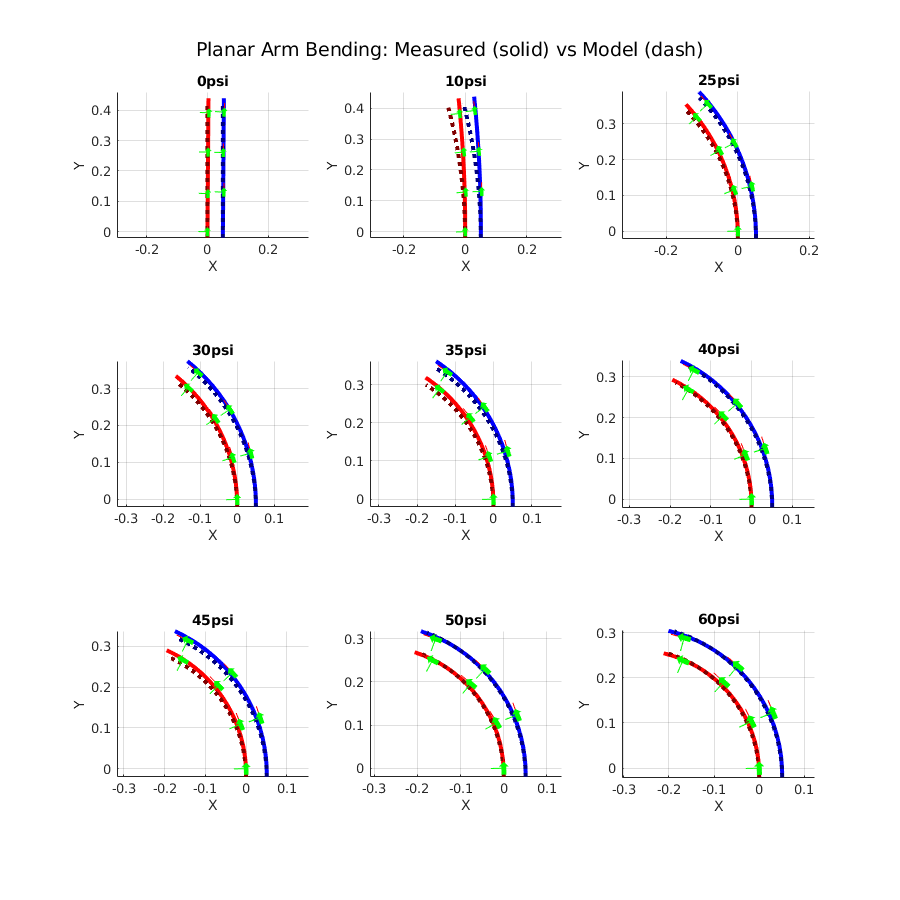

sgtitle("Planar Arm Bending: Measured (solid) vs Model (dash)")
set(gcf, 'position', [0, 0, 900, 900])

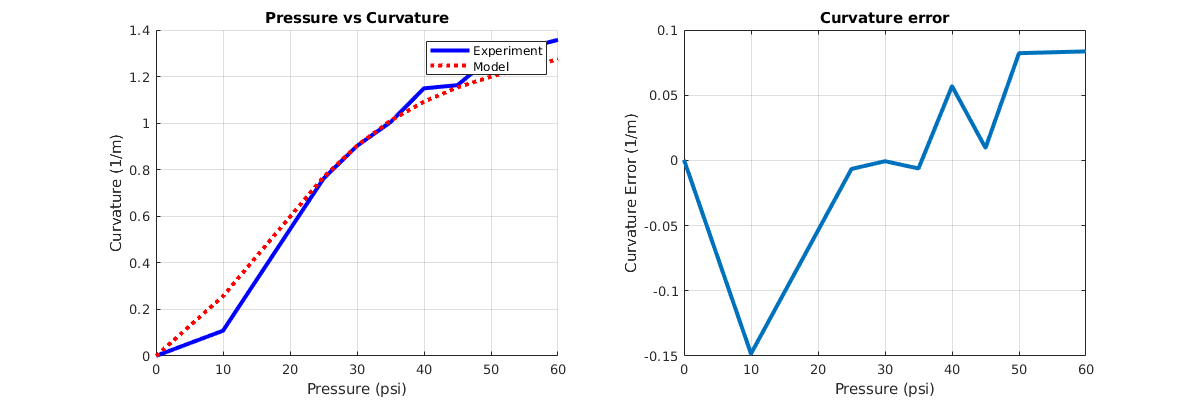

figure()
set(gcf, 'position', [0, 0, 1200, 400])
subplot(1, 2, 1)
hold on
plot(experiment_pressures, mat_h_o_fit(3, :), 'b', 'linewidth', 3)
plot(experiment_pressures, mat_h_o_model(3, :), 'r:', 'LineWidth', 3)
legend(["Experiment", "Model"])
title("Pressure vs Curvature")
xlabel("Pressure (psi)")
ylabel("Curvature (1/m)")
grid on

subplot(1, 2, 2)
plot(experiment_pressures, mat_h_o_fit(3, :) - mat_h_o_model(3, :), 'linewidth', 3);
grid on
title("Curvature error")
xlabel("Pressure (psi)")
ylabel("Curvature Error (1/m)")

## Planar Arm Wide Dataset

%% Define Regular Planar Arm Params
experiment_name = "planar_arm_wide";

%% Parameterize tag locations
% ids of tags along the arm (and the order that we will store them in)
planar_arm_tags = [6 7 8 9 12 13 14]; % Tags 6 to 9 

% the muscles that these muscles are attached to (in the same order) 
muscle_ids = [1 1 1 1 2 2 2]; % List of muscle ids that the tags are attached to, in order

% Define t_tags: Percentage of tag position along total length of arm
% Tag in the middle of arm: t = 0.5
muscle_length_cm = 18 * 2.54;
muscle_spacing_cm = 13;
base_offset_cm = 2;
t_tags = ([0, 1, 2, 3, 1, 2, 3] * muscle_spacing_cm + base_offset_cm) / muscle_length_cm;

rho = 2.5/2 * 0.0254; % m, Half of separator size

% Construct pose matrices
% Transform from world frame to base curve
g_1 = SE2(0, -base_offset_cm / 100, pi/2);

g_o_1 = SE2(0, rho, 0); % Muscle 1
g_o_2 = SE2(0, -rho, 0); % Muscle 2
g_o = g_1 * inv(g_o_1); % Central muscle
g_o_muscles = {g_1; g_o * g_o_2};

%% Plot the comparisons
% Pressures corresponding to each experiment bag file in order
experiment_pressures = [10 15 20 25 30 35 40 45 50];

fig = figure();
mat_h_o_model = zeros(3, length(experiment_pressures));
mat_h_o_fit = zeros(3, length(experiment_pressures));
for i = 1 : length(experiment_pressures)
    subplot(3, 3, i)
    [mat_h_o_model(:, i), mat_h_o_fit(:, i)] =  ...
        plot_exp_comparison_2d(i, experiment_name, experiment_pressures, g_o, g_o_muscles, planar_arm_tags, muscle_ids, t_tags); % TODO: Update 
    title(sprintf("%dpsi", experiment_pressures(i)))
end

Testing with bag: localized-10psi_2021-12-15-12-50-30.bag
Testing with bag: localized-15psi_2021-12-15-12-50-13.bag
Testing with bag: localized-20psi_2021-12-15-12-49-50.bag
Testing with bag: localized-25psi_2021-12-15-12-49-26.bag
Testing with bag: localized-30psi_2021-12-15-12-49-01.bag
Testing with bag: localized-35psi_2021-12-15-12-48-34.bag
Testing with bag: localized-40psi_2021-12-15-12-48-07.bag
Testing with bag: localized-45psi_2021-12-15-12-47-42.bag
Testing with bag: localized-50psi_2021-12-15-12-46-36.bag


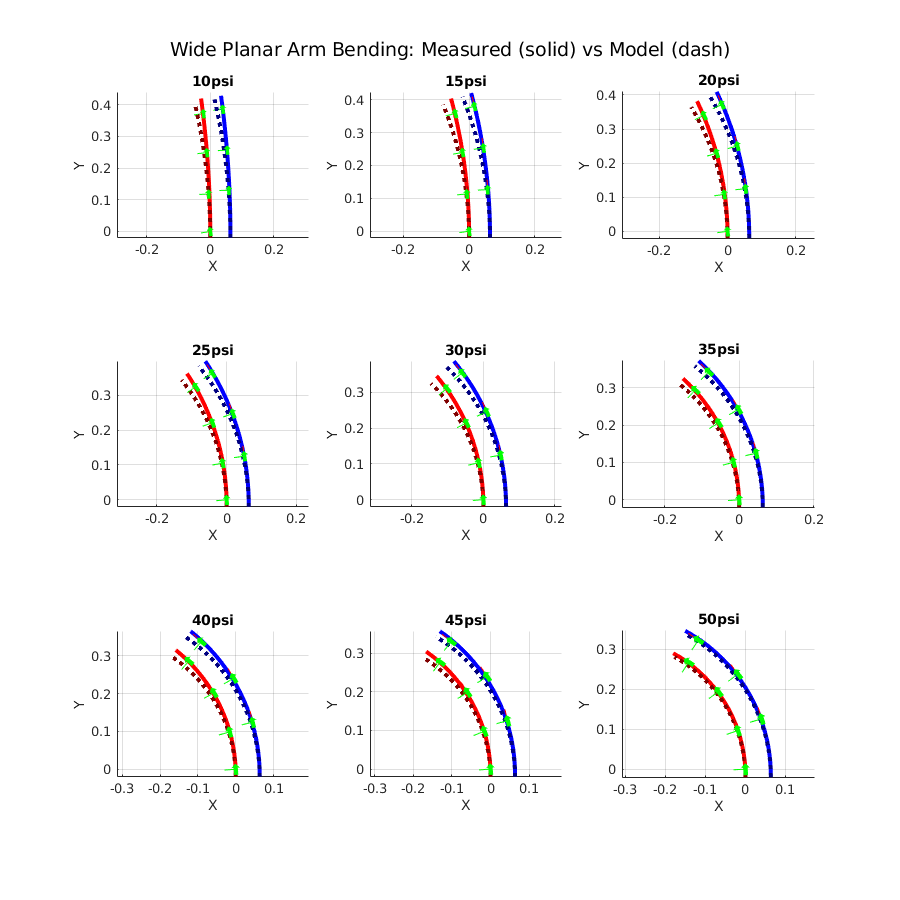

sgtitle("Wide Planar Arm Bending: Measured (solid) vs Model (dash)")
set(gcf, 'position', [0, 0, 900, 900])

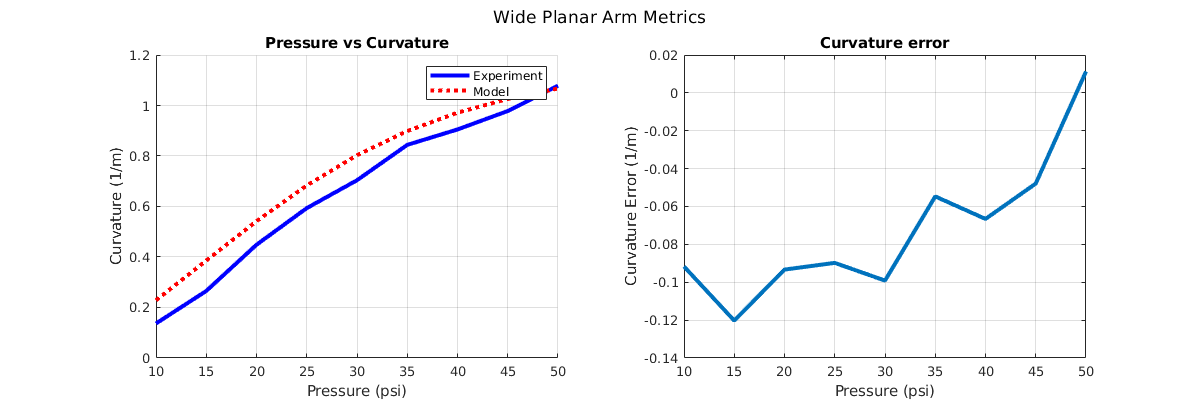

figure()
sgtitle("Wide Planar Arm Metrics")
set(gcf, 'position', [0, 0, 1200, 400])
subplot(1, 2, 1)
hold on
plot(experiment_pressures, mat_h_o_fit(3, :), 'b', 'linewidth', 3)
plot(experiment_pressures, mat_h_o_model(3, :), 'r:', 'LineWidth', 3)
legend(["Experiment", "Model"])
title("Pressure vs Curvature")
xlabel("Pressure (psi)")
ylabel("Curvature (1/m)")
grid on

subplot(1, 2, 2)
plot(experiment_pressures, mat_h_o_fit(3, :) - mat_h_o_model(3, :), 'linewidth', 3);
grid on
title("Curvature error")
xlabel("Pressure (psi)")
ylabel("Curvature Error (1/m)")